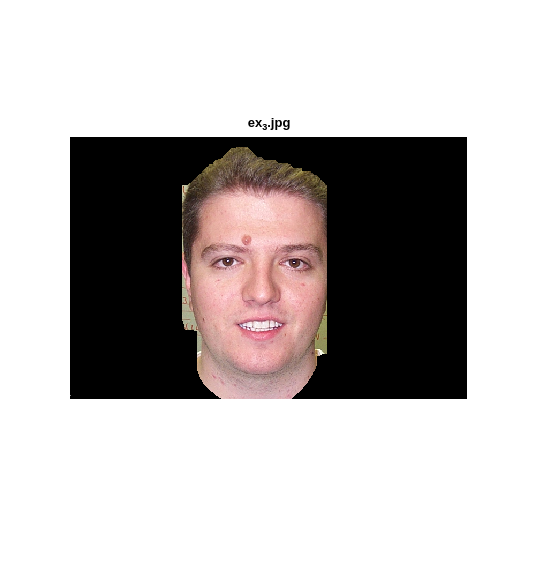

clear all

% Load face images from a folder
imageDir = 'Faces/';
imageDir2 = 'Faces/DB2/';
testimages = dir(fullfile(imageDir, '*.jpg'));
testimages2 = dir(fullfile(imageDir2, '*.jpg'));
allImages = [testimages; testimages2];
numImages = numel(allImages);

% Read images into a cell array
faceData = cell(1, numImages);
for i = 1:numImages
    % Load your image
    im = im2double(imread(fullfile(allImages(i).folder, allImages(i).name)));
    mask = double(testa(im));
    imshow(im.*mask);title(allImages(i).name)

xlim([98 839])
ylim([45 534])
    % try
    %     [eye1,eye2] = findEyes(im);
    % 
    %     imX = showEyes(im, eye1, eye2);
    %     imshow(imX);title(allImages(i).name)
    % catch
    %     disp("Error in " + allImages(i).name)
    % end
    pause(0.01)
end

## TEsts

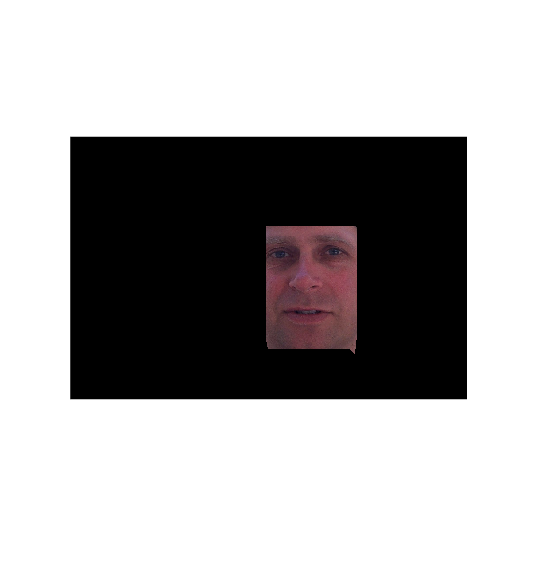

    % Load your image
    im = im2double(imread("Faces/DB2/il_" + 1 + ".jpg"));
    mask = double(testa(im));
    imshow(im.*mask);

    % [eye1,eye2] = findEyes(im);
    % 
    % imX = showEyes(im, eye1, eye2);
    % imshow(imX);
    pause(0.1)

function test = testa(imIn)
%imIn = im2double(imread("Faces/db1_" + 3 + ".jpg"));
imIn = im2double(imIn);
imIn = adjustRGB(imIn);
%imIn = colorCorrection(imIn);
imIn = contrastStretchColor(imIn,0,1);
hsv = rgb2hsv(imIn);
ycbcr = rgb2ycbcr(imIn);


% Convert the RGB image to YCgCr color space
ycgcrImage = rgb2ycgcr(imIn);

% Extract the Y, Cb, and Cr channels
Y = ycgcrImage(:, :, 1);
Cg = ycgcrImage(:, :, 2);
Cr = ycgcrImage(:, :, 3);

Cb = histeq(ycbcr(:,:,2));

H = hsv(:,:,1);
% Define thresholds for skin color in YCbCr space
% Trail and Error Values

Cbmin = .28;
Cbmax = 0.75;

Ymin = .55;
Ymax = 1;

Cgmin = .4;
Cgmax = .545;
Crmin = 0.0015;
Crmax = 0.2;

Hmin = 0.09;
Hmax = 0.8;

cbmask = ~(Cbmin <= Cb & Cb <= Cbmax);
SE = strel('disk', 6);
cbmask = imerode(cbmask, SE);
cbmask = imclose(cbmask, SE);

SE = strel('disk', 19);% was 8 before 2023-11-22
cbmask = imdilate(cbmask, SE);
cbmask = imclose(cbmask, SE);

% Filter image, retaining only the 5 objects with the largest areas.
SE = strel('disk', 50);
cbmask = imclose(cbmask, SE);
cbmask = keepNLargestObjects(cbmask, 3);

cbmask = imfill(cbmask, 'holes');
SE = strel('disk', 10);
cbmask = imdilate(cbmask, SE);


crmask = (Crmin <= Cr & Cr <= Crmax);
SE = strel('disk', 2);
crmask = imclose(crmask, SE);
SE = strel('disk', 12);
crmask = imerode(crmask, SE);
SE = strel('rectangle', [80 5]);
crmask = imclose(crmask, SE);
SE = strel('rectangle', [80 5]);
crmask = imopen(crmask, SE);
SE = strel('rectangle', [5 10]);
crmask = imopen(crmask, SE);
crmask = imfill(crmask, 'holes');
crmask = keepNLargestObjects(crmask, 3);

%SE = strel('disk', 40);
%crmask = imopen(crmask, SE);
%imshow(crmask); title('crmask')

cgmask = (Cgmin <= Cg & Cg <= Cgmax);
%imshow(cgmask); title('cgmask')

ymask = (Ymin <= Y & Y <= Ymax);
SE = strel('disk', 24);
ymask = imdilate(ymask, SE);
ymask = imfill(ymask, 'holes');
ymask = keepNLargestObjects(ymask, 3);

hmask = (H <= Hmin | Hmax <= H);
SE = strel('disk', 6);
hmask = imerode(hmask, SE);
hmask = imclose(hmask, SE);

SE = strel('disk', 19);% was 8 before 2023-11-22
hmask = imdilate(hmask, SE);
hmask = imclose(hmask, SE);

% Filter image, retaining only the 5 objects with the largest areas.
SE = strel('disk', 50);
hmask = imclose(hmask, SE);
hmask = keepNLargestObjects(hmask, 3);

hmask = imfill(hmask, 'holes');
SE = strel('disk', 10);
hmask = imdilate(hmask, SE);

mask = crmask & cbmask & hmask & ymask & cgmask;
%imshow(mask); title("mask")
% Create binary masks for skin regions
mask = keepNLargestObjects(mask, 2);
SE = strel('rectangle', [100 260]);
mask = imclose(mask, SE);
SE = strel('rectangle', [100 5]);
mask = imclose(mask, SE);
SE = strel('rectangle', [250 1]);
mask = imopen(mask, SE);
mask = keepNLargestObjects(mask, 1);

    %imshow(mask); title('mask')
test = mask;
%imshow(mask.*imIn); title('mask')
end

function [mask] = faceMask(rgbImage)
    HSV = rgb2hsv(rgbImage);
    H = HSV(:,:,1);
    YCBCR = rgb2ycbcr(rgbImage);
    Cb = YCBCR(:,:,2);

    for i = 1:length(rgbImage(:,1,1))
        for j = 1:length(rgbImage(1,:,1))
           R = rgbImage(i,j,1);
           G = rgbImage(i,j,2);
           B = rgbImage(i,j,3);
           
           if ( H(i,j) < 0.85 && H(i,j) > 0.09)
               rgbImage(i,j,1) = 0;
               rgbImage(i,j,2) = 0;
               rgbImage(i,j,3) = 0;
           end
       
           if ( Cb(i,j) > 130 && Cb(i,j) < 100)
               rgbImage(i,j,1) = 0;
               rgbImage(i,j,2) = 0;
               rgbImage(i,j,3) = 0;
           end

        end
    end

    rgbImage = imbinarize(im2double(rgbImage(:,:,1)));
    
    % Clean the image
    rgbImage = imerode(rgbImage,strel('disk',2));
    rgbImage = imerode(rgbImage,strel('disk',1));
    rgbImage = imdilate(rgbImage,strel('disk',8));
    
    rgbImage = imfill(double(rgbImage));
    
    rgbImage = imdilate(rgbImage,strel('disk',8));
 
    rgbImage = imfill(double(rgbImage));
    
    rgbImage = imerode(rgbImage,strel('disk',10));
    
    mask = imerode(rgbImage,strel('disk',5));
end

function ycgcrImage = rgb2ycgcr(rgbImage)
    % Define the conversion matrix for RGB to YCgCr
    conversionMatrix = [0.299 0.587 0.114; -0.1687367 -0.331264 0.5; 0.5 -0.418688 -0.081312];
    
    % Convert the RGB image to YCgCr
    [rows, cols, ~] = size(rgbImage);
    ycgcrImage = zeros(rows, cols, 3);
    
    for i = 1:rows
        for j = 1:cols
            pixel = double(reshape(rgbImage(i, j, :), 3, 1));
            ycgcrPixel = conversionMatrix * pixel;
            ycgcrImage(i, j, :) = ycgcrPixel;
        end
    end

    % Normalize the YCgCr channels
    ycgcrImage(:, :, 2) = ycgcrImage(:, :, 2) + 0.5;
    ycgcrImage = min(max(ycgcrImage, 0), 1);
end
function adaptedImage = adjustRGB(imIn)
% Function for adjustment of color balance in RGB image using chromatic adaptation

% Turn image to double
imIn = im2double(imIn);

% Specify the illuminant color using illumwhite
illuminantColor = illumwhite(imIn, 1);

% Perform chromatic adaptation
adaptedImage = chromadapt(imIn, illuminantColor,'ColorSpace', 'prophoto-rgb');
end
